%% finite-difference code
%Cartesion coordinates, basic case  
%X22B01T0 means left side is insulated, RS constant flux q0, initial T = 0.
%DO NOT CONFUSE q = (1-s) with q0 (constant flux W/m2K)

## dimensions

clear
close all
clc
format compact

alpha = 1.5e-7; L=0.02;
q0 = 10; %W/m^2k
dt = 10;
dx = 0.001;
Tinf = 1.0; %constant environmental temp at right-side surface
k = 0.5; %thermal conductivity, W/mK
h = 25; %heat transfer coefficient, W/m^2K
m = q0*dx/k; %dimensionless cofficient
Ti = 0; %initial temp
tf = 7200; %last time, sec
time = 0:dt:tf; %time
x = 0:dx:L; x = x'; %space
xp = 100*x; %for plotting
n = round(L/dx)+1; %total number of spatial nodes

## set up coefficients that do not change with space or time

T = zeros(n, 1);%initial condition
s=0.5;%coefficient  0.5 = Crank-Nicolson
q=(1-s);%cofficient used later in d matrix
f = alpha*dt/dx^2;
crit = 2*(1+m) %convergence criterion for fully explicit

crit =    2.040000000000000

M = dx^2/(alpha*dt)  %for fully explicit, M must be >=2*(1+m)

M =    0.666666666666667

a = -s*f;
b = 1+2*s*f;
c = -s*f;

## Set up tridiagonal matrix, A does not change with time

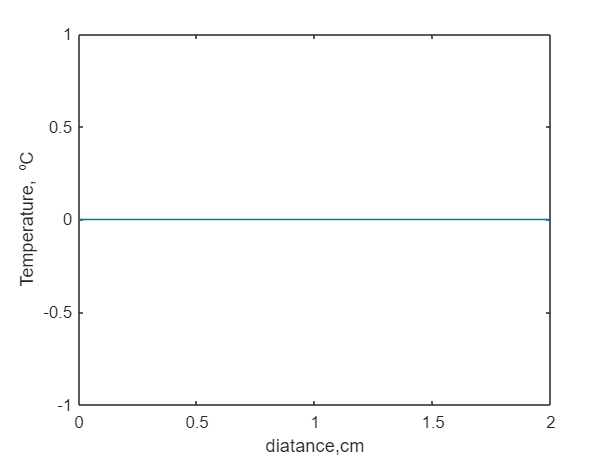

%# rows = number of nodes.
Tp = T;%for plotting
figure
plot(xp, Tp);
hold on
xlabel('diatance,cm')
ylabel('Temperature, ^oC')

A = diag(b*ones(n,1))+diag(a*ones(n-1, 1),-1)+diag(c*ones(n-1,1),1);
A(1,2) = a+c;
A(n, n-1) = a+c; A(n,n) = b;%last row is different due to insulated left B.C.

## set up time loop with right-side vector that has temps from prior time

`dimensionless temperature (TT) at insulated boundary node for comparison:  Define this from www.exact.unl.edu solution, X22B10T0 Eq. 2 (Their solution is reversed, so q0 is on the left side)`

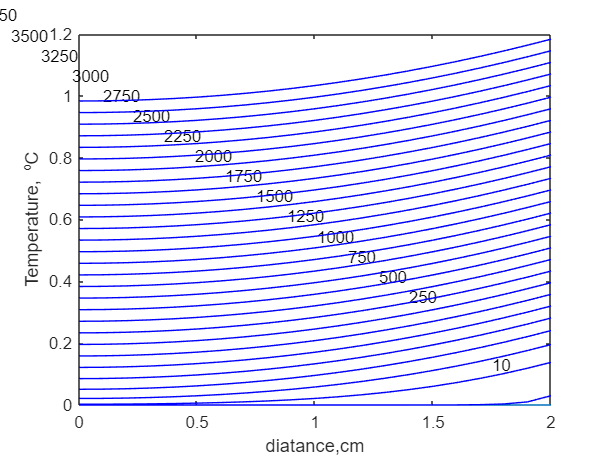

tint = 1; %plotting interval
theta(1) = 1.0;%dimensionless temp ratio for centertemp
kx = 0; ky = 0;
d = zeros(n, 1); %initialize right-side vector
for j = dt:dt:tf %time loop for inside nodes
    for i=2:n-1
        d(i) = q*f*T(i-1)+(1-2*q*f)*T(i)+q*f*T(i+1);
    end
    d(1) = (1-2*q*f)*T(1)+2*q*f*T(2);
    d(n) = 2*q*f*T(n-1)+(1-2*q*f)*T(n)+2*m*(q*f-c);
    T=A\d;
    if j==dt %plot T at the first dt
        Tp = T; %for plotting
        plot(xp, Tp, 'b-');
        text(1.75,0.13,num2str(j));
        count = 1; %count = lines plotted
    end
    if (rem(tint,25)==0) %plot only 25th result
        Tp = T; %for plotting
        plot(xp, Tp, 'b-');
        if count == 1
            kx = kx+4; ky = ky+5; %bumps the test on the plot up for the 3rd line
        else
            kx = kx+1.3; ky = ky+1.3; %default offset for text
        end
        text(1.8-0.1*kx, 0.1+0.05*ky, num2str(j)) %offsets text to the left and up
        count = count + 1;%count the number of lines plotted
    end
    %compute dimensionless T ratio to verify with Heisler chart
    %theta(tint+1) = (T(1)-Tinf)/(Ti-Tinf);
    TT(tint+1)=T(1)/( q0*L/k ); %temp at insulated boundary at time =j, to compare to exa
    tint = tint+1;
end

## dimensionless time for Heisler charts

Bi = h*L/k  %Biot number

Bi =      1

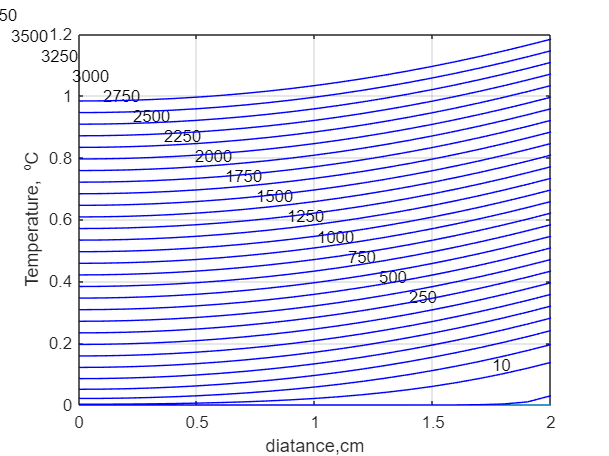

%onebyBi=k/(h*L)
format long
Fo = alpha*time/L^2;
%Fotheta = [Fo' Theta'];
FoT = [Fo' TT'];
grid on

%% define TT and error for the 3 requested cases
%need to type in the exact solution results from www.exact.unl.edu for the 3 cases 
%suggested code to find dimensionless temp when Fo=0.12
k1=find(abs(FoT(:,1)-0.12)<1e-6);%k1=index when Fo =0.12
TT12=TT(k1) %TT12=dimensionless temp when Fo=0.12

TT12 =    0.014932147301151

error12 = (TT12-0.01488727)*100

error12 =    0.004487730115107


k2=find(abs(FoT(:,1)-0.30)<1e-6);%k1=index when Fo =0.30
TT3=TT(k2) %TT12=dimensionless temp when Fo=0.30

TT3 =    0.143698253901705

error3 = (TT3-0.14382443)*100

error3 =   -0.012617609829538


k3=find(abs(FoT(:,1)-0.60)<1e-6);%k1=index when Fo =0.60
TT6=TT(k3) %TT12=dimensionless temp when Fo=0.60

TT6 =    0.433675587605165

error6 = (TT6-0.43387651)*100

error6 =   -0.020092239483543